# **Circuitos Electricos II**

**Roberto Sanchez Figueroa    **

**brrsanchezfi@unal.edu.co**

# **Soluciones propuestas para los ejercicios del taller 7**

## EJERCICIO 1

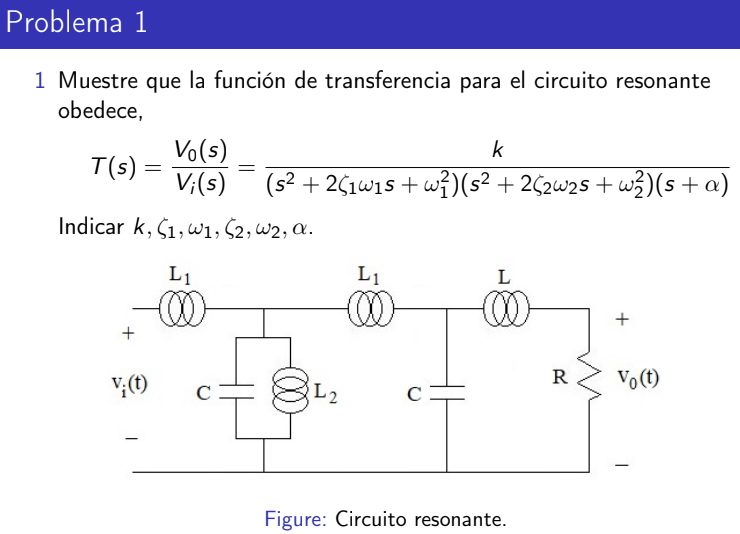

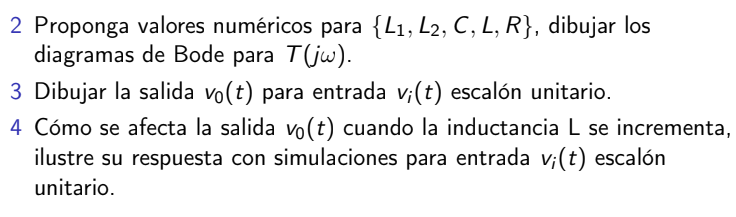

syms V_i L_1 L_2 C L R V_o s I_1 I_2 I_3 

%valores

L1 = 2;
L2 = 2;
L0 = 4;
C1 = 2;
R1 = 100;

%en este ejercicio puedo plantear 4 mallas, sin embargo basta con hallas el
%equivalente entre el paralelo de  c y l2, el cual llamo P_LCL2

P_CL2 = paralelo((1/(C*s)),(L_2*s));

%planteo las ecuaciones de cada malla

malla1 = V_i == (L_1*s + P_CL2)*I_1 - (P_CL2)*I_2;

malla2 = 0 == (P_CL2 + L_1*s + (1/(C*s)))*I_2 - (P_CL2)*I_1 - (1/(C*s))*I_3;

malla3 = 0 == ((1/(C*s)) + L*s + R)*I_3 - (1/(C*s))*I_2 ;

%armo la matriz y la soluciono con el comando solve

sys = [ malla1;
        malla2;
        malla3];

sol = solve(sys,[I_1 I_2 I_3]);

I_1d = simplify(sol.I_1);
I_2d = simplify(sol.I_2);
I_3d = simplify(sol.I_3)

$$I\_3d = \frac{L_{2}\,V_{i}}{{L_{1}}^{2}\,s+L_{1}\,R+L_{2}\,R+L\,L_{1}\,s+L\,L_{2}\,s+2\,L_{1}\,L_{2}\,s+C\,L\,{L_{1}}^{2}\,s^{3}+C\,{L_{1}}^{2}\,L_{2}\,s^{3}+C\,{L_{1}}^{2}\,R\,s^{2}+C^{2}\,L\,{L_{1}}^{2}\,L_{2}\,s^{5}+C^{2}\,{L_{1}}^{2}\,L_{2}\,R\,s^{4}+3\,C\,L\,L_{1}\,L_{2}\,s^{3}+3\,C\,L_{1}\,L_{2}\,R\,s^{2}}$$


%%ESTE ES OTRO METODO PARA RESOLVELA, DEPEJO I1 PARA LUEGO SUSTITUIR EN I2
%%Y POSTEIORMENTE SUSTITUIR EN I3

        % I_1d = solve(malla1,I_1)
        % 
        % malla2 = subs(malla2,I_1,I_1d)
        % 
        % I_2d = solve(malla2,I_2)
        % 
        % malla3 = subs(malla3,I_2,I_2d)
        % 
        % I_3d = solve(malla3,I_3)

%Basicamente lo que quiero es hallar el voltaje en la resistencia por tanto
%solo me interesa I_3, por ley de ohm hallo el voltaje en la resistencia 

V_o = R*I_3d;

%despejo la funcion de tranferencia

T_s = (V_o/V_i)

$$T\_s = \frac{L_{2}\,R}{{L_{1}}^{2}\,s+L_{1}\,R+L_{2}\,R+L\,L_{1}\,s+L\,L_{2}\,s+2\,L_{1}\,L_{2}\,s+C\,L\,{L_{1}}^{2}\,s^{3}+C\,{L_{1}}^{2}\,L_{2}\,s^{3}+C\,{L_{1}}^{2}\,R\,s^{2}+C^{2}\,L\,{L_{1}}^{2}\,L_{2}\,s^{5}+C^{2}\,{L_{1}}^{2}\,L_{2}\,R\,s^{4}+3\,C\,L\,L_{1}\,L_{2}\,s^{3}+3\,C\,L_{1}\,L_{2}\,R\,s^{2}}$$

dem_T_s = (1/T_s)*(L_2*R)

$$dem\_T\_s = {L_{1}}^{2}\,s+L_{1}\,R+L_{2}\,R+L\,L_{1}\,s+L\,L_{2}\,s+2\,L_{1}\,L_{2}\,s+C\,L\,{L_{1}}^{2}\,s^{3}+C\,{L_{1}}^{2}\,L_{2}\,s^{3}+C\,{L_{1}}^{2}\,R\,s^{2}+C^{2}\,L\,{L_{1}}^{2}\,L_{2}\,s^{5}+C^{2}\,{L_{1}}^{2}\,L_{2}\,R\,s^{4}+3\,C\,L\,L_{1}\,L_{2}\,s^{3}+3\,C\,L_{1}\,L_{2}\,R\,s^{2}$$

%sustituyo valores

T_s = (subs(T_s,[L_1 L_2 C L R],[L1 L2 C1 L0 R1]))

$$T\_s = \frac{200}{128\,s^{5}+3200\,s^{4}+144\,s^{3}+3200\,s^{2}+28\,s+400}$$


%convierto

T_s = sym2tf(T_s,0)

T_s =
 
                        50
  -----------------------------------------------
  32 s^5 + 800 s^4 + 36 s^3 + 800 s^2 + 7 s + 100
 
Continuous-time transfer function.




%luego necesito hallar las raices para calcular los cortes de la funcion de
%tranferencia

[num,dem] = tfdata(T_s)

num = 1×1 cell array
    {[0 0 0 0 0 50]}


dem = 1×1 cell array
    {[32 800 36 800 7 100]}


sympref('FloatingPointOutput',true);
syms s
factorizacion = (poly2sym(cell2mat(dem),s));
factorizacion = factor(factorizacion,'FactorMode',"real")

$$factorizacion = \left(\begin{array}{cccc} 32 & s+24.9950 & s^{2}+0.0043\,s+0.1465 & s^{2}+7.3153e-04\,s+0.8536 \end{array}\right)$$

conj_1 = sym2poly(factorizacion(3)) %complejo conjugado 1

conj_1 =     1.0000    0.0043    0.1465


conj_2 = sym2poly(factorizacion(4)) %complejo conjugado 2

conj_2 =     1.0000    0.0007    0.8536




a = sym2poly(-1*root(factorizacion(2)))

a = 24.9950

w_10 = (abs(imag(root(factorizacion(3)))))

$$w\_10 = \left(\begin{array}{c} 0.3827\\ 0.3827 \end{array}\right)$$

w_20 = (abs(imag(root(factorizacion(4)))))

$$w\_20 = \left(\begin{array}{c} 0.9239\\ 0.9239 \end{array}\right)$$

k = (double(factorizacion(1))/((conj_1(3)^2)*(conj_2(3)^2))) %num(1) expresion inicial

k = 2.0463e+03

  %ganancia
% k = cell2mat(num(1))./(((conj_1(3))*(conj_2(3))))
k=  cell2mat(num(1))   /   ( (conj_1(3))*(conj_2(3))   *   sym2poly(factorizacion(1))  * a)

k =          0         0         0         0         0    0.4999


k = k(6) 

k = 0.4999

ganancia = 20*log10(k)

ganancia = -6.0225

zita_1 =  conj_1(2)/(2*sqrt(conj_1(3)))

zita_1 = 0.0056

zita_2 =  conj_2(2)/(2*sqrt(conj_2(3)))

zita_2 = 3.9589e-04

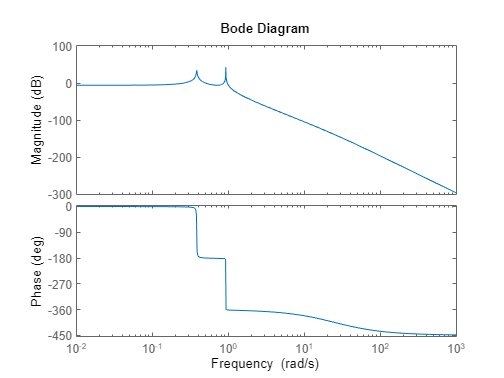

%diagrama de bode del sistema
bode(T_s)

En esta grafica se puede observar todas las caracteristicas obtenidas

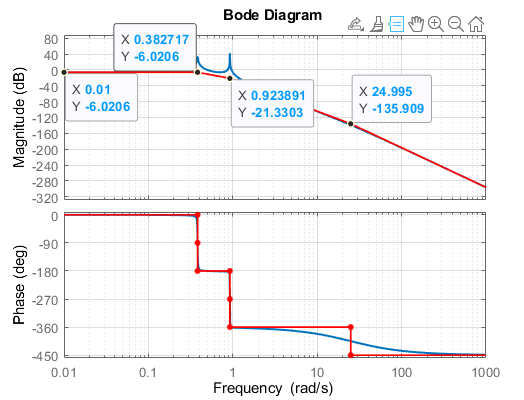

#### Simulacion

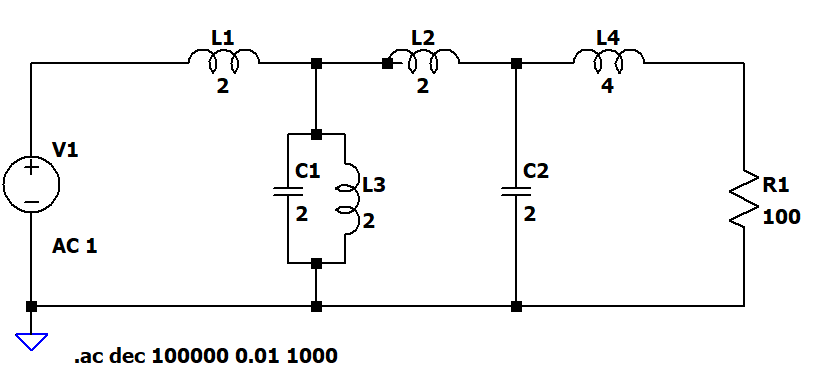

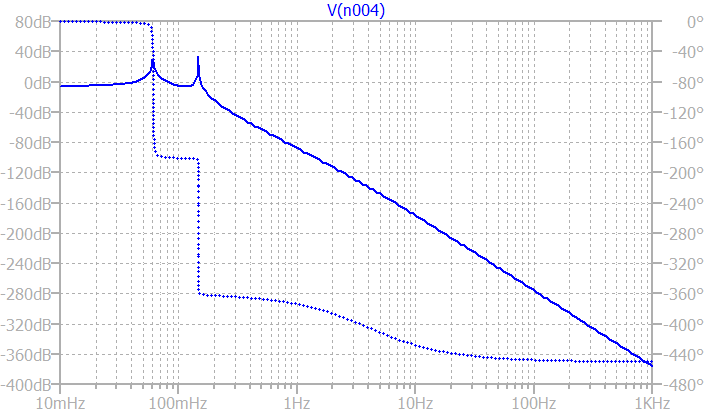

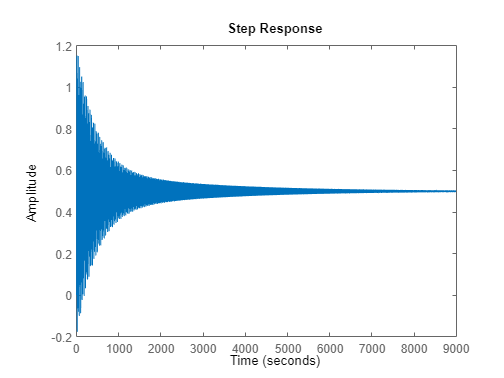

step(T_s)

#### simulacion cambiando el parametro de L

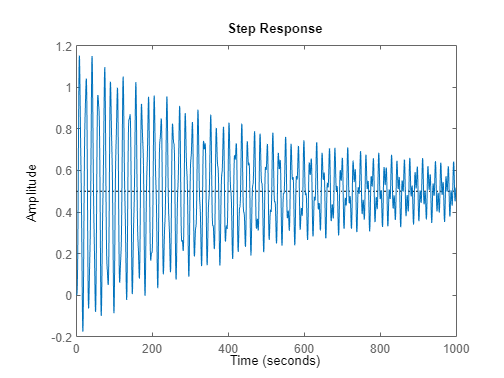

% en LTSPICE se puede configurar un step param para tener elementos
% variables, en el archivo de github dejo guardado el archivo de simulacion
% para que se pueda ver con mas detalle por que la variacion en 'L' no es
% muy notable

step(T_s)
axis([0,1e3,-0.2, 1.2])

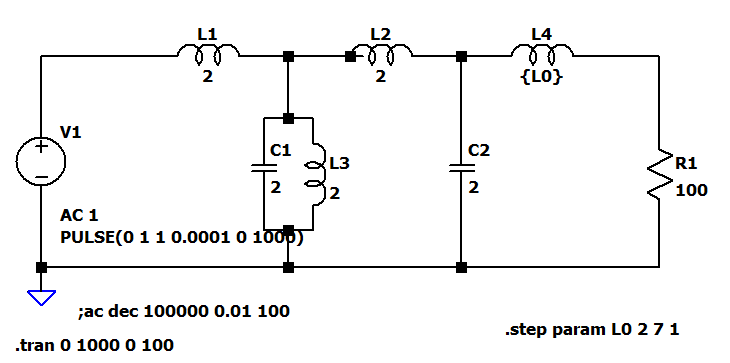

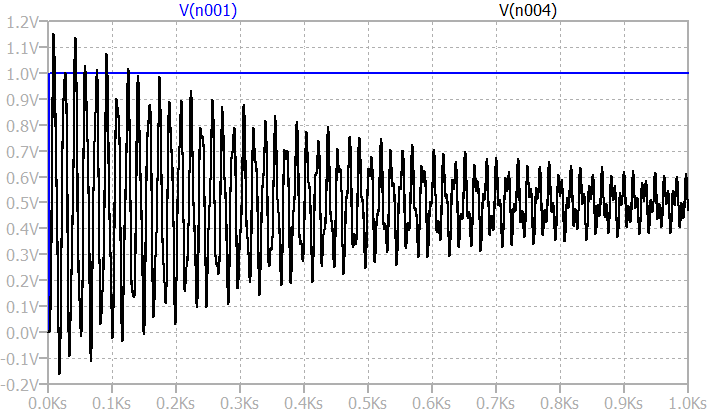

## EJERCICIO 2

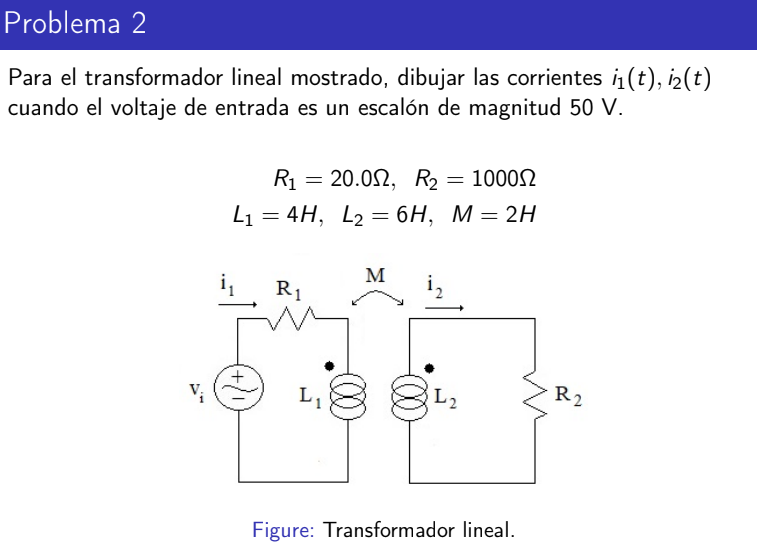

% datos
syms R_1 R_2 L_1 L_2 M V_i I_1 I_2 s Vi

% el escalon con magnitud 50V convertida a laplace
V_i = 50/s;

R1 = 20;
R2 = 1000;
L1 = 4;
L2 = 6;
M1 = 2;

% mismo analisis de mallas 

malla1 = Vi == (R_1 + L_1*s)*I_1 - (M*s)*I_2

$$malla1 = \mathrm{Vi}=I_{1}\,\left(R_{1}+L_{1}\,s\right)-I_{2}\,M\,s$$


malla2 = 0 == -(L_2*s + R_2)*I_2 + (M*s)*I_1

$$malla2 = 0=I_{1}\,M\,s-I_{2}\,\left(R_{2}+L_{2}\,s\right)$$



%matriz de mi sistema 
sys2 = [malla1;malla2]

$$sys2 = \left(\begin{array}{c} \mathrm{Vi}=I_{1}\,\left(R_{1}+L_{1}\,s\right)-I_{2}\,M\,s\\ 0=I_{1}\,M\,s-I_{2}\,\left(R_{2}+L_{2}\,s\right) \end{array}\right)$$

sol2 = solve(sys2,[I_1 I_2]);

%soluciones
I_1 = sol2.I_1

$$I\_1 = \frac{\mathrm{Vi}\,\left(R_{2}+L_{2}\,s\right)}{R_{1}\,R_{2}-M^{2}\,s^{2}+L_{1}\,R_{2}\,s+L_{2}\,R_{1}\,s+L_{1}\,L_{2}\,s^{2}}$$

I_2 = sol2.I_2

$$I\_2 = \frac{M\,\mathrm{Vi}\,s}{R_{1}\,R_{2}-M^{2}\,s^{2}+L_{1}\,R_{2}\,s+L_{2}\,R_{1}\,s+L_{1}\,L_{2}\,s^{2}}$$


%sustitucion
I_1 = subs(I_1,[R_1 R_2 L_1 L_2 M Vi],[R1 R2 L1 L2 M1 V_i])

$$I\_1 = \frac{50\,\left(6\,s+1000\right)}{s\,\left(20\,s^{2}+4120\,s+20000\right)}$$

I_2 = subs(I_2,[R_1 R_2 L_1 L_2 M Vi],[R1 R2 L1 L2 M1 V_i])

$$I\_2 = \frac{100}{20\,s^{2}+4120\,s+20000}$$


%tranformada inversa y respuesta 
I_1t = simplify(ilaplace(I_1))

$$I\_1t = 2.5000-2.5000\,{\mathrm{e}}^{-103\,t}\,\left(\cosh\left(98.0255\,t\right)+0.9895\,\sinh\left(98.0255\,t\right)\right)$$

I_2t = simplify(ilaplace(I_2))

$$I\_2t = 0.0510\,{\mathrm{e}}^{-103\,t}\,\sinh\left(98.0255\,t\right)$$

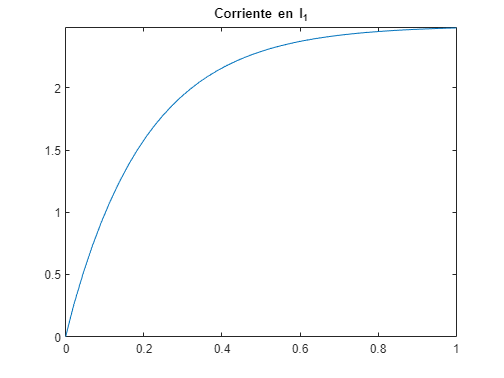


%%%respuesta al escalon
fplot(I_1t,[0 1])
title("Corriente en I_1")

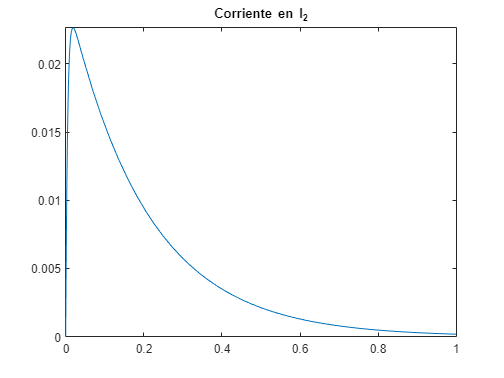

fplot(I_2t,[0 1])
title("Corriente en I_2")

## EJERCICIO 3

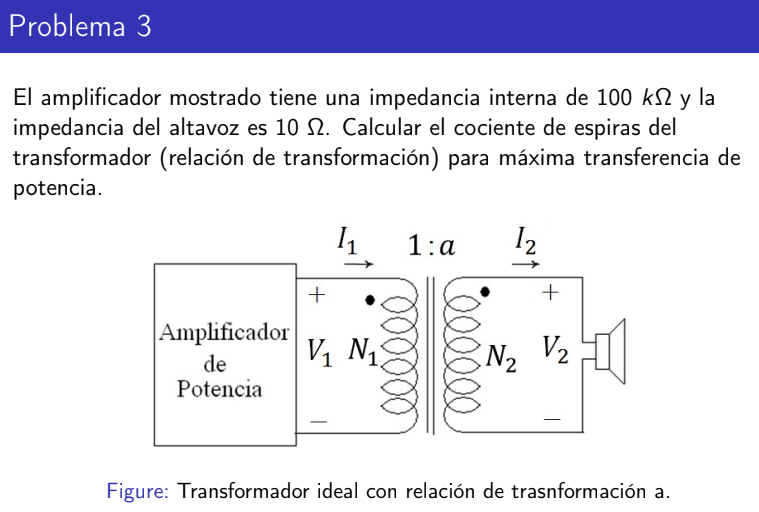

Sadiku pag 464  Maxima tranferencia de potencia

Sadiku pag 594 Ejercicio similar

Maxima transferencia de potencia


$$p=i^{2} R_{L}=\left(\frac{V_{\mathrm{Th}}}{R_{\mathrm{Th}}+R_{L}}\right)^{2} R_{L}$$
        

esto lo que quiere decir es que si ambos sistemas tienen la  misma impedancia, entonces la transferencia de potencia sera maxima

Luego:


$$Z_{\textrm{Th}} =\frac{Z_L }{n^2 }\;\Longrightarrow \;n^2 =\frac{Z_L }{Z_{\textrm{Th}} }=\frac{10\Omega }{100k\Omega }=\sqrt{\frac{1}{10}}=\frac{1}{100}=0\ldotp 01$$


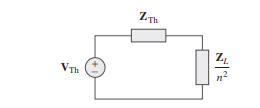

function x = paralelo(n1,n2)

    x = (n1*n2)/(n1+n2);

end

function t_sym = tf2sym(H) 
       [num,den] = tfdata(H);
       syms s;
       t_sym = simplify(poly2sym(cell2mat(num),s)/poly2sym(cell2mat(den),s));
end

function [ tfobj ] = sym2tf( symobj, Ts) %pasa de sym a tf    Ts es el samplin, para continuas dejar en 0
    % SYM2TF convert symbolic math rationals to transfer function
    
    if isnumeric(symobj)
        tfobj=symobj;
        return;
    end
    
    [n,d]=numden(symobj);
    num=sym2poly(n);
    den=sym2poly(d);
    
    if nargin==1
        tfobj=tf(num,den);
    else
        tfobj=tf(num,den,Ts);
    end
end
